clc;
clear;
load ('Workspace.mat');

Price = totalReturns(:,1:4);
R = [(Price(2:end,:)-Price(1:end-1,:))./(Price(1:end-1,:)) totalReturns(2:end, 5)];
Ryear = [(((1+R(:,1:4).^12)-1)) totalReturns(2:end,5)];

muT = mean(R);
sigmaT = diag(cov(R))';
Sigma = cov(R(:,3:4));
var = [Sigma(1,1) Sigma(2,2)];
sigma = sqrt(var);
mu = muT(:,3:4)';
one = ones(length(Sigma), 1);
Sigmainv = inv(Sigma);
A = one'/Sigma*one;
B = one'/Sigma*mu;
C = mu'/Sigma*mu;
D = A*C - B^2;

% minimum-variance set
mup = 0.002:0.00001:0.012;
sigmap2 = (A*mup.^2 - 2*B*mup + C)/D;
sigmap = sqrt(sigmap2);

% global minimum variance portfolio
wg = Sigma\one/A;
mug = B/A;
sigmag = sqrt(1/A);

% % slope portfolio
Rs = 0;
wslope = Sigma\(mu - Rs*one)/(B - A*Rs);
muslope = (C - B*Rs)/(B - A*Rs);
sigmaslope = sqrt(C - 2*Rs*B + A*Rs^2)/abs(B - A*Rs);

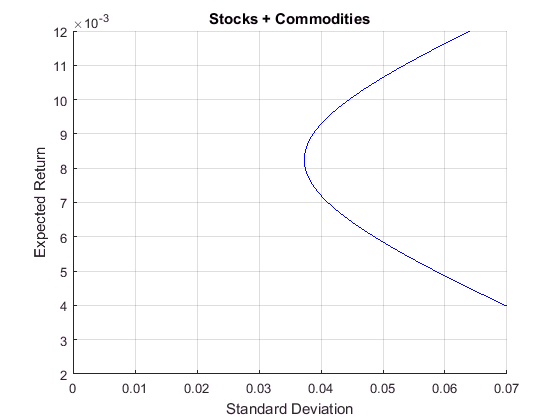

figure
%plot(sigma,mu,'o'); 
hold on;
xlabel('Standard Deviation'), ylabel('Expected Return'), axis([0, 0.07, 0.002, 0.012]);
title('Stocks + Commodities');
grid;
hold on
plot(sigmap, mup, 'b');
%plot(sigmag,mug,'s');
%plot(sigmaslope,muslope,'s');
hold off

%% (a) - ii
Sigma = cov(R(:,2:4));
var = [Sigma(1,1) Sigma(2,2) Sigma(3,3)];
sigma = sqrt(var);
mu = muT(:,2:4)';
one = ones(length(Sigma), 1);
Sigmainv = inv(Sigma);
A = one'/Sigma*one;
B = one'/Sigma*mu;
C = mu'/Sigma*mu;
D = A*C - B^2;

% minimum-variance set
mup = 0.002:0.00001:0.012;
sigmap2 = (A*mup.^2 - 2*B*mup + C)/D;
sigmap = sqrt(sigmap2);

% global minimum variance portfolio
wg = Sigma\one/A;
mug = B/A;
sigmag = sqrt(1/A);

% slope portfolio
Rs = 0;
wslope = Sigma\(mu - Rs*one)/(B - A*Rs);
muslope = (C - B*Rs)/(B - A*Rs);
sigmaslope = sqrt(C - 2*Rs*B + A*Rs^2)/abs(B - A*Rs);

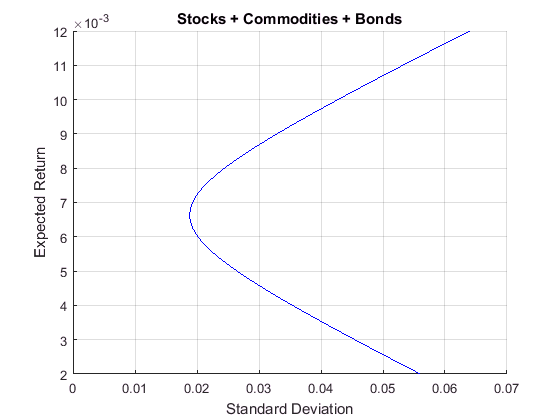

figure
%plot(sigma,mu,'o'); 
hold on;
xlabel('Standard Deviation'), ylabel('Expected Return'), axis([0, 0.07, 0.002, 0.012]);
grid;
title('Stocks + Commodities + Bonds');
hold on
plot(sigmap, mup, 'b');
%plot(sigmag,mug,'s');
%plot(sigmaslope,muslope,'s');
hold off

%% (a) - iii
Sigma = cov(R(:,1:4));
var = [Sigma(1,1) Sigma(2,2) Sigma(3,3) Sigma(4,4)];
sigma = sqrt(var);
mu = muT(:,1:4)';
one = ones(length(Sigma), 1);
Sigmainv = inv(Sigma);
A = one'/Sigma*one;
B = one'/Sigma*mu;
C = mu'/Sigma*mu;
D = A*C - B^2;

% minimum-variance set
mup = 0.002:0.00001:0.012;
sigmap2 = (A*mup.^2 - 2*B*mup + C)/D;
sigmap = sqrt(sigmap2);

% global minimum variance portfolio
wg = Sigma\one/A;
mug = B/A;
sigmag = sqrt(1/A);

% slope portfolio
Rs = 0;
wslope = Sigma\(mu - Rs*one)/(B - A*Rs);
muslope = (C - B*Rs)/(B - A*Rs);
sigmaslope = sqrt(C - 2*Rs*B + A*Rs^2)/abs(B - A*Rs);

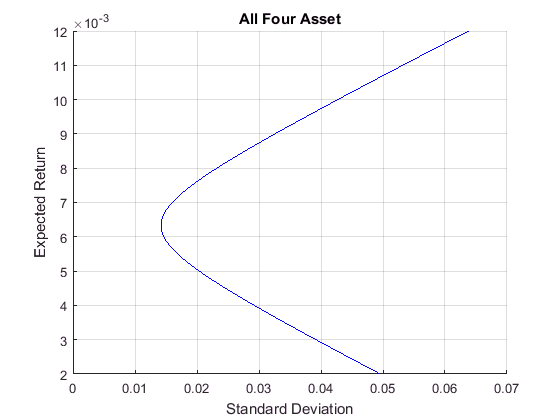

figure
%plot(sigma,mu,'o'); 
hold on;
xlabel('Standard Deviation'), ylabel('Expected Return'), axis([0, 0.07, 0.002, 0.012]);
grid;
title('All Four Asset');
hold on
plot(sigmap, mup, 'b');
%plot(sigmag,mug,'s');
%plot(sigmaslope,muslope,'s');
hold off

%% (b)
TargetReturn = 0.0100;
x = find(mup == TargetReturn);
StdTarget = sigmap(x); % The standard deviation on a monthly basis

% Let's now find out the weights of this portfolio
Lambda = (C - (TargetReturn*B))/D;
Gamma = ((TargetReturn*A) - B)/D;
wmv = Lambda*(Sigmainv*one) + Gamma*(Sigmainv*mu)

wmv =    0.147534762293809
   0.116475612342083
   0.962328136026627
  -0.226338510662519


SIGMA = sqrt((A * TargetReturn^2 -2 * B * TargetReturn + C)./D)

SIGMA =    0.042701603247128


% cumsum(w)
% The sum of all the weights is equal to 1. GOOD. These are te weights of
% the minimum varaince portfolio that achieve a target return of 0.0100 on
% monthly basis

%% (c) - Introducing a utility Function
a = 6;
woptimal = ((1-B/a)/A*Sigmainv*one + 1/a*Sigmainv*mu)'

woptimal =    0.800950334254443  -0.196912150102777   0.430098494272237  -0.034136678423907


% Again the cumsum = 1
muoptimal = (1-B/a)/A*B + C/a

muoptimal =    0.007714181679741


varoptimal = (1-B/a)/A + muoptimal/a;
sigmaoptimal = sqrt(varoptimal)

sigmaoptimal =    0.020801771809416


% Corresponding Indifference Curve
Ustar = muoptimal-a/2*varoptimal;
sigmaIndiff = [0:0.001:0.25]';
muIndiff = Ustar+a/2*sigmaIndiff.^2;

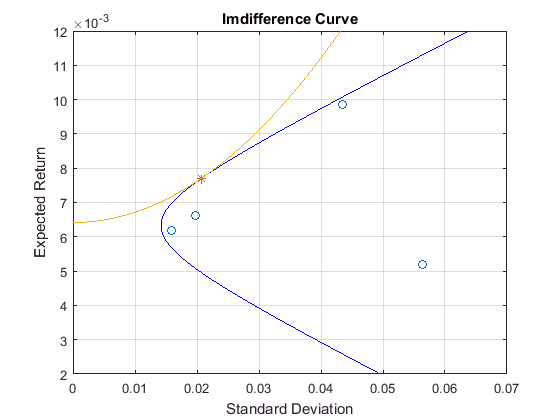

figure
plot(sigma,mu,'o');
xlabel('Standard Deviation'), ylabel('Expected Return'), axis([0, 0.07, 0.002, 0.012]);
grid;
title('Imdifference Curve');
hold on
plot(sigmap, mup, 'b');
plot(sigmaoptimal,muoptimal,'*');
plot(sigmaIndiff, muIndiff);
hold off

%% (d) - Riskless asset also available for investment
R = 0.0040; %the risk-free rate

% minimum-variance set
sigmapriskless = abs(mup - R)/sqrt(C - 2*R*B + A*R^2);

% tangency portfolio
wtan = Sigmainv*(mu - R*one)/(B - A*R);
mutan = (C - B*R)/(B - A*R);
sigmatan = sqrt(C - 2*R*B + A*R^2)/abs(B - A*R);

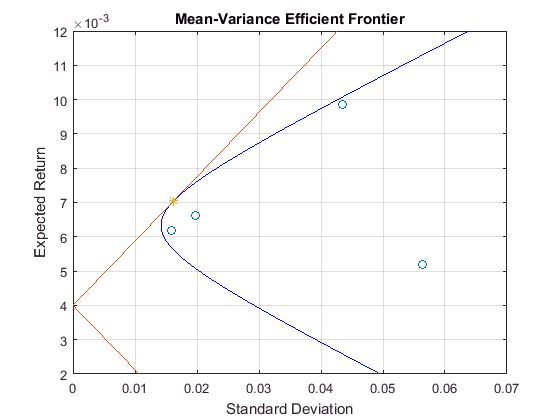

figure
plot(sigma,mu,'o');
xlabel('Standard Deviation'), ylabel('Expected Return'), axis([0, 0.07, 0.002, 0.012]);
grid;
title('Mean-Variance Efficient Frontier');
hold on
plot(sigmap, mup, 'b');
plot(sigmapriskless, mup);
plot(sigmatan,mutan,'*');
hold off

%% (e) - Optimal portfolio for the investor with risk-free asset

%--optimal portfolio for particular risk aversion
woptimal = 1/a*(Sigma\(mu-R))

woptimal =    1.905495500903791
  -0.553873105883853
   0.529422348265605
   0.041831841274447


% Here the cumsum() is different from 1. This means that we borrow the risk
%-free asset to invest it in risky assets.
muoptimal = R+woptimal'*(mu-R)

muoptimal =    0.009863764293112


varoptimal = woptimal'*Sigma*woptimal;
sigmaoptimal = sqrt(varoptimal)

sigmaoptimal =    0.031261702590423


% corresponding indifference curve
Ustar = muoptimal-a/2*varoptimal;
sigmaIndiff = [0:0.001:0.25]';
muIndiff = Ustar+a/2*sigmaIndiff.^2;

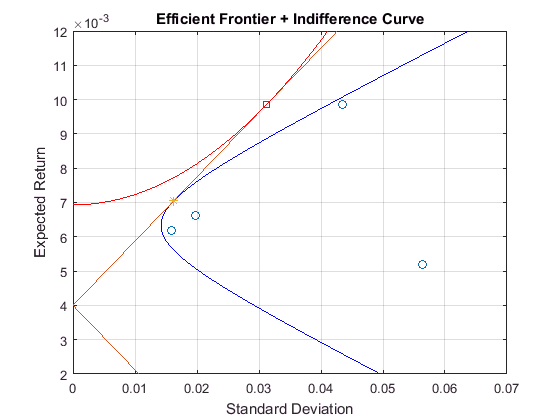

figure
plot(sigma,mu,'o');
xlabel('Standard Deviation'), ylabel('Expected Return'), axis([0, 0.07, 0.002, 0.012]);
grid;
title('Efficient Frontier + Indifference Curve');
hold on
plot(sigmap, mup, 'b');
plot(sigmapriskless, mup);
plot(sigmatan,mutan,'*');
plot(sigmaoptimal,muoptimal,'s');
plot(sigmaIndiff, muIndiff, 'r');
hold off

% As stated before in the code, the investor borrows money (sell the risk
% free asset in order to invest it the risky assets
Port = sum(woptimal) - 1

Port =    0.922876584559990
